**Introduction**

This document is to explore the waveform of OTFS in ***fractional Dopplers*** for ***rectangular pulses***. 

**Basic settings**

clear;
clc;
N = 4;                          % time slot number
M = 4;                         % subcarrier number
% x
x_value = 1+1j;
x_delay_pos = 1:4;
x_doppl_pos = 1:4;
x_num = length(x_delay_pos);
X_DD = zeros(N, M);    
for x_id = 1:x_num
    X_DD(x_doppl_pos(x_id), x_delay_pos(x_id)) = x_value;
end
% channel
his = [1,1, 1];
lis = [0,1, 1];
kis = [-1.2, 1.3, 1.4];
cp_len = 4

cp_len = 4

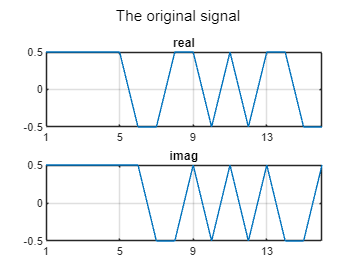

% modulation
s = OTFS_modulation(N,M,X_DD);
s_mat = reshape(s, M,N).';
plot_s(s, M, N);

% add cp
s_cp = [s(N*M-cp_len+1:N*M);s];

**Case 1: Emanuele Viterbo Channel in time domain**

We pass the signal through the channel first.

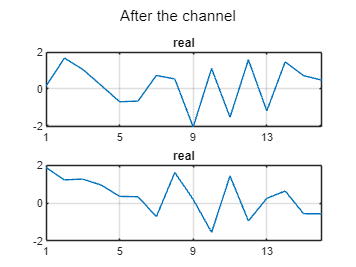

% pass the channel
s_chan = 0;
for p_id = 1:length(his)
    hi = his(p_id);
    li = lis(p_id);
    ki = kis(p_id);
    s_chan = s_chan + hi*circshift([s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)],li);
end
r = s_chan(cp_len+1:cp_len+(N*M));
r_mat = reshape(r, M, N).';
plot_r(r, M, N);

% to Rx DD domain
Y_DD = OTFS_demodulation(N,M,r);


1st, we need  to generate the channel in the DD domain using perfect CSI

[H, HDD] = OTFS_ddchannel_gen(M, N, length(his),lis,kis,his, "real_channel", true);
xDD = X_DD.';
xDD = xDD(:);
yDD = Y_DD.';
yDD = yDD(:);
yDD2 = HDD*xDD;
yDD_diff = abs(yDD - yDD2);
fprintf("The yDD difference is %e\n", sum(yDD_diff));

The yDD difference is 7.526409e-15


if sum(yDD_diff > 1e-13) > 0
    error("  - there are element-wise difference.");
else
    disp("  - all elements are equal.");
end

  - all elements are equal.


Then, we estimate the channel in the DD domain

hi_est = zeros(N, 1);
ki_est = zeros(N, 1);
li_est = zeros(N, 1);
for N_id = 1:N
    ch_est_delay = 3;
    ch_est_doppl = N_id;
    ki_est(N_id) = ch_est_doppl - 1;
    li_est(N_id) = ch_est_delay - 1;
    pss_beta = exp(1j*2*pi*(1 - 1)/M*(ch_est_doppl - 1)/N);
    hi_est(N_id) = Y_DD(ch_est_doppl, ch_est_delay)/x_value/pss_beta;
end
[~, HDD_est] = OTFS_ddchannel_gen(M, N, N,li_est,ki_est,hi_est);
disp("- Rough estimation");

- Rough estimation


HDD_est_err = abs(HDD_est - HDD);
fprintf("  - The HDD_est error is %e\n", sum(HDD_est_err, "all"));

  - The HDD_est error is 1.439758e+02


yDD_est_diff = abs(HDD_est*xDD - yDD);
fprintf("  - The yDD_est difference is %e\n", sum(yDD_est_diff));

  - The yDD_est difference is 1.546690e+01


If you look at $y$, you will realize that the channe is different when the pilots are different. The reason is that the path difference is $e^{\frac{j2\pi k_i l}{MN}}$ while we use $e^{\frac{j2\pi k' l}{MN}}$ to estimate the channel. Now, we try to use the correct coefficient to cancel it.

hi_est2 = zeros(N, 1);
ki_est2 = ki*ones(N, 1);
li_est2 = zeros(N, 1);
for N_id = 1:N
    ch_est_delay = 3;
    ch_est_doppl = N_id;
    li_est2(N_id) = ch_est_delay - 1;
    pss_beta = exp(1j*2*pi*(1 - 1)/M*ki/N);
    hi_est2(N_id) = Y_DD(ch_est_doppl, ch_est_delay)/x_value/pss_beta;
end
[~, HDD_est2] = OTFS_ddchannel_gen(M, N, N,li_est2,ki_est2,hi_est2);
disp("- Accurate estimation (impossible)");

- Accurate estimation (impossible)


HDD_est_err2 = abs(HDD_est2 - HDD);
fprintf("  - The HDD_est error is %e\n", sum(HDD_est_err2, "all"));

  - The HDD_est error is 1.472264e+02


yDD_est_diff2 = abs(HDD_est2*xDD - yDD);
fprintf("  - The yDD_est difference is %e\n", sum(yDD_est_diff2));

  - The yDD_est difference is 3.343482e+01


We compare whether the time domain value we calculate is correct.

r_est = zeros(M*N, 1);
for t = 1:M*N
    for p_id = 1:length(his)
        hi = his(p_id);
        li = lis(p_id);
        ki = kis(p_id);
        if t - li <= 0
            t_org = t - li + M*N_id;
        else
            t_org = t - li;
        end
        r_est(t)=r_est(t)+s(t_org)*hi*exp(2j*pi*ki*(t-li-1)/M/N);
    end
end
r_diff = abs(r_est - r);
fprintf("The time domain diff is %e\n",sum(r_diff, "all"));

The time domain diff is 3.504872e-15


assert(sum(r_diff, "all")/M/N < sqrt(2)*eps);

Now, we need to estimate the accurate channel

Y_DD_est = zeros(N, M);
for l = 1:M
    for k = 1:N
        for k2 = unique(x_doppl_pos)
            for p_id = 1:length(his)
                hi = his(p_id);
                li = lis(p_id);
                ki = kis(p_id);
                l_org = l - li;
                if l_org < 1
                    l_org = l_org + M;
                end
                k_org = k - ki;
                if k_org < 1
                    k_org = k_org + N;
                end
                x_val_org = X_DD(k2, l_org);
                yest = hi*(exp(2j*pi*(k2+ki-k))-1)/(exp(2j*pi*(k2+ki-k)/N)-1)*exp(2j*pi*ki*(l-li-1)/M/N)*x_val_org/N;
                if l - li < 1
                    yest = yest*exp(-2j*pi*(k2-1)/N);
                end
                Y_DD_est(k, l) = Y_DD_est(k, l) + yest;
            end
        end
    end
end
Y_DD_diff = abs(Y_DD_est - Y_DD);
fprintf("The DD domain diff is %e\n",sum(Y_DD_diff, "all"));

The DD domain diff is 1.589824e-14


assert(sum(Y_DD_diff, "all")/N/M < 1e-13);

**Channel Estimation**

We are going to build a channel estimation

Y_DD_est_CE = zeros(N,M);

for k = 1:N
    for l = 1:M
        % combine with the a path gain
        for lj = 0:1
            for ki2 = -2:1
                l_x = l - lj;
                k_x = mod(k - ki2-1,N)+1;
                beta = 1;
                if l_x < 1
                    l_x = l_x + M;
                    beta = exp(-2j*pi*(k_x-1)/N);
                end
                % if abs(X_DD(k_x, l_x)) <= eps
                %     continue;
                % end
                % we have an actual path
                if ismember(lj, lis)
                    hijs = his(lis == lj);
                    kis_set = kis(lis == lj);
                    total_gain = 0;
                    for hij_id = 1:length(hijs)
                        hij = hijs(hij_id);
                        ki = kis_set(hij_id);
                        total_gain = total_gain + hij*exp(2j*pi*ki*(l-lj-1)/M/N)*(exp(2j*pi*(k_x+ki-k))-1)/(exp(2j*pi*(k_x+ki-k)/N)-1)/N;
                    end
                    Y_DD_est_CE(k, l) = Y_DD_est_CE(k, l) + X_DD(k_x, l_x)*beta*total_gain;
                end
            end
        end
    end
end
Y_DD_est_CE_diff = abs(Y_DD_est_CE - Y_DD);
Y_DD_est_CE_diff_mean = mean(Y_DD_est_CE_diff, "all");
fprintf("The Y_DD(CE) diff: %e\n", Y_DD_est_CE_diff_mean);

The Y_DD(CE) diff: 1.068497e-15


assert(Y_DD_est_CE_diff_mean < 1e-13);

Now, we try a second method, to isolate k from the path gain

Y_DD_est_CE2 = zeros(N,M);

for k = 1:N
    for l = 1:M
        % combine with the a path gain
        for lj = 0:1
            for ki2 = -2:1
                l_x = l - lj;
                k_x = mod(k - ki2-1,N)+1;
                beta = 1;
                if l_x < 1
                    l_x = l_x + M;
                    beta = exp(-2j*pi*(k_x-1)/N);
                end
                % if abs(X_DD(k_x, l_x)) <= eps
                %     continue;
                % end
                % we have an actual path
                if ismember(lj, lis)
                    hijs = his(lis == lj);
                    kis_set = kis(lis == lj);
                    total_gain = 0;
                    for hij_id = 1:length(hijs)
                        hij = hijs(hij_id);
                        ki = kis_set(hij_id);
                        if k-ki2 >=1  && k-ki2 <=N
                            total_gain = total_gain + hij*exp(2j*pi*ki*(l-lj-1)/M/N)*(exp(2j*pi*(ki-ki2))-1)/(exp(2j*pi*(k_x+ki-k)/N)-1)/N;
                        else
                            total_gain = total_gain + hij*exp(2j*pi*ki*(l-lj-1)/M/N)*(exp(2j*pi*(ki-ki2+N))-1)/(exp(2j*pi*(k_x+ki-k)/N)-1)/N;
                        end
                    end
                    Y_DD_est_CE2(k, l) = Y_DD_est_CE2(k, l) + X_DD(k_x, l_x)*beta*total_gain;
                end
            end
        end
    end
end
Y_DD_est_CE_diff2 = abs(Y_DD_est_CE2 - Y_DD);
Y_DD_est_CE_diff_mean2 = mean(Y_DD_est_CE_diff2, "all");
fprintf("The Y_DD(CE) diff: %e\n", Y_DD_est_CE_diff_mean2);

The Y_DD(CE) diff: 1.159828e-15


assert(Y_DD_est_CE_diff_mean2 < 1e-13);

**Functions**

function plot_s(s, M, N)
    figure("name", "The original signal")
    subplot(2,1,1)
    plot(real(s));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(s));
    title("imag");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("The original signal")
end
function plot_r(r, M, N)
    figure("name", "Time domain")
    subplot(2,1,1)
    plot(real(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("After the channel")
end
